
TT =

     []


TT =

     []


TT =

     []


TT =

     []


TT =

     []


TT =

     []


TT =

     []


TT =

     []


TT =

     []


TT =

     []


TT =

     []


TT =

     []


TT =

     []


TT =

     []


TT =

     []


TT =

     []


TT =

     []


TT =

     []


TT =

     []


TT =

     []


TT =

     []


TT =

     []


TT =

     []


TT =

     []


TT =

     []


TT =

     []


TT =

     []


TT =

     []


TT =

     []


TT =

     []



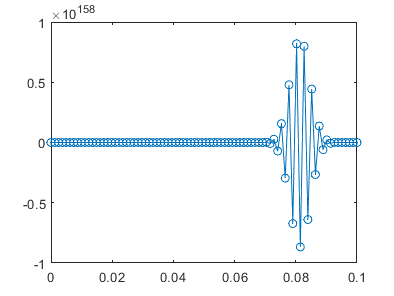

R = 0.1;      %m
k = 20;       %W/mK
S = 1000;     %W/m^3
h = 50;       %W/m^2K
Tw = 20;      %C

N = 81;
r = linspace(0,R,N+1); 
dr = r(2) - r(1);
dt = 0.005; 
tf = 30*dt;
M = tf/dt;
T=[];
u = ones(N+1,1);

for n=1:M
	un=u;
    u(1)=0;
    u(2)=u(1);
    for i=2:N
		u(i)=un(i)+dt*k*((un(i+1)-un(i-1))/(2*r(i)*dr)+(un(i+1)-2*un(i)+un(i+1))/dr^2+S);
    end
    u(N+1)=Tw-(k/(h*dr))*(un(N)-un(N-1));
    Tw-T-(k/(h*dr))*(un(2)-un(1))==0;
    TT=T
    plot(r,u,'-o')
    pause(0.2)
end